load('trav_gyro_sys.mat')
% bodemag(trav_gyro_sys);
% 
% hold on
% plot(trav_gyro_plant.o2i1x,trav_gyro_plant.g,Color='red')
% xlim([3,200])
% % legend('Simulation','Mesurmants')
% % legend("Position",[0.19082,0.73016,0.27246,0.10558])
% hold off;grid on
% 
% h = bodeplot(trav_gyro_sys);
% setoptions(h,'MagVisible','off');
% hold on
% plot(trav_gyro_plant.o2i1x,trav_gyro_plant.p,Color='red')
% xlim([3,200])
% legend('Simulation','Mesurmants')
% legend("Position",[0.19082,0.73016,0.27246,0.10558])
% hold off

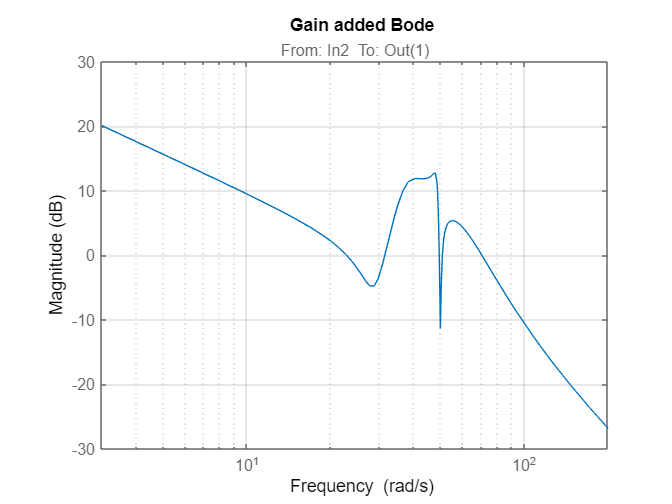

figure;
gain_trav_gyro = 8000;
trav_gyro_plant_gain = gain_trav_gyro ;
gained_trav_gyro = gain_trav_gyro *trav_gyro_sys;
bodemag(gained_trav_gyro)
grid on
xlim([3,200])
title('Gain added Bode')

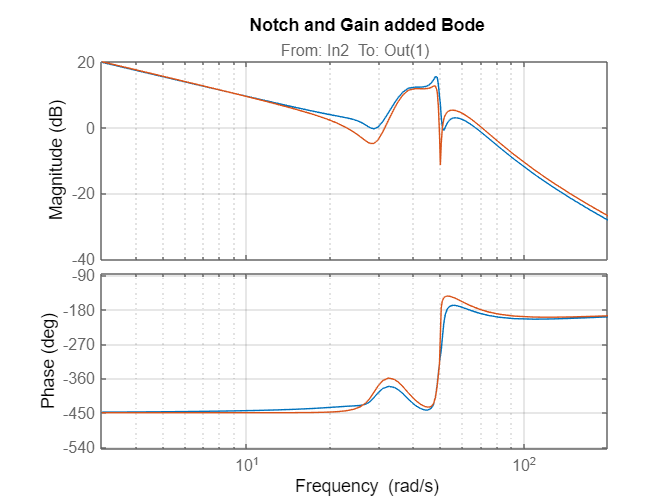

figure;
load('trav_gyro_notch_30hz.mat')
trav_gyro_notch_30 = tf(trav_gyro_notch_30hz);
load('trav_gyro_notch_50hz.mat')
trav_gyro_notch_50 = tf(trav_gyro_notch_50hz);
bode(trav_gyro_notch_50hz*trav_gyro_notch_30hz*gained_trav_gyro);
hold on;
bode(gained_trav_gyro)
xlim([3,200])
hold off
grid on
title('Notch and Gain added Bode')

sys_trav_gyro = trav_gyro_notch_50hz*trav_gyro_notch_30hz*gained_trav_gyro;
%opts = pidtuneOptions('PhaseMargin',45);
[C_pi_trav_gyro,info] = pidtune(sys_trav_gyro,'PI',35.0)

C_pi_trav_gyro =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.354, Ki = 0.217
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 0
    CrossoverFrequency: 35
           PhaseMargin: NaN


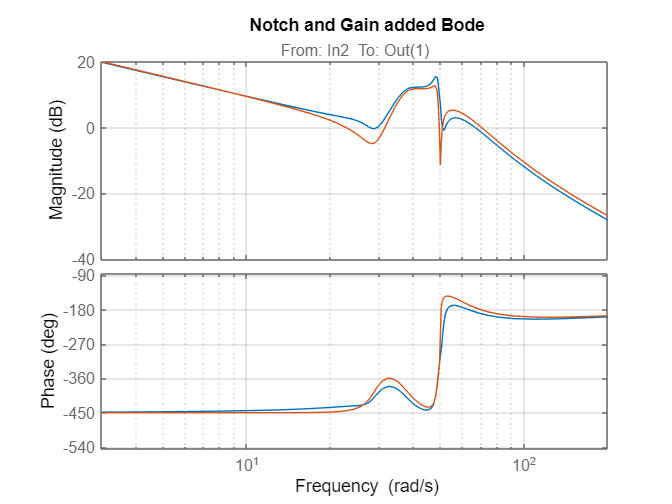


sys_control = C_pi_trav_gyro*sys_trav_gyro;
% bode(sys_control) 
%xlim([1,100])
grid on

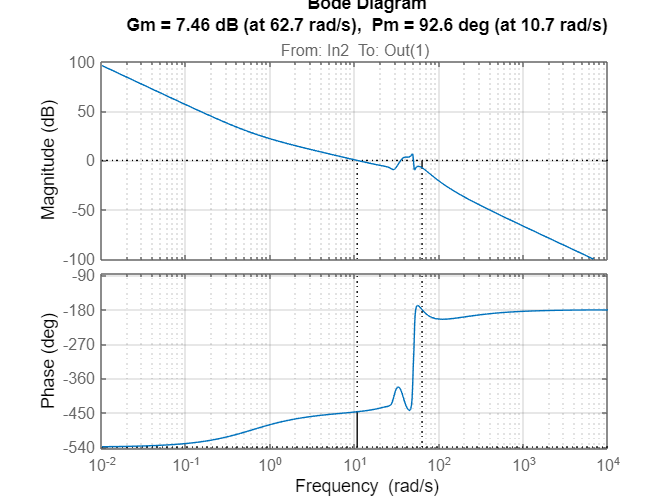

figure;
margin(sys_control)
grid on

allmargin(sys_control)

ans = struct with fields:
     GainMargin: [2.4301 2.3596 Inf]
    GMFrequency: [52.6425 62.7095 Inf]
    PhaseMargin: [92.5808 150.1642 -136.4091]
    PMFrequency: [10.6632 35.0001 49.5063]
    DelayMargin: [0.1515 0.0749 0.0788]
    DMFrequency: [10.6632 35.0001 49.5063]
         Stable: 0


PC_trav_gyro =sys_control;